# Spike prediction

## Calculate probabilities

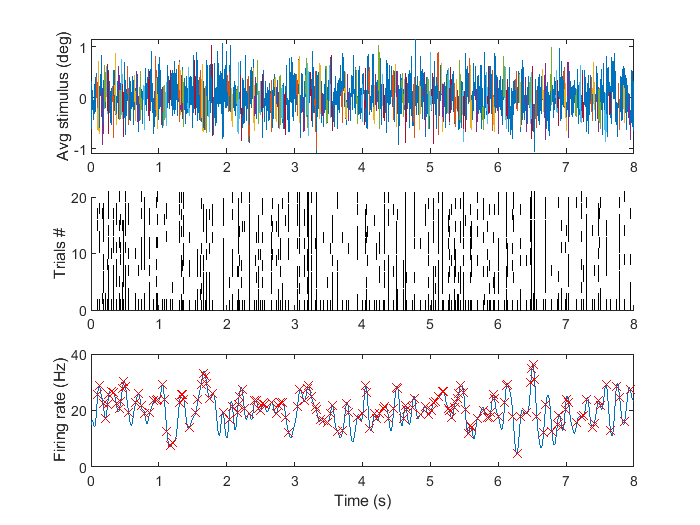

stimulus_test = stimulus(:,8*fs+1:end);
raster_data_test = raster_data(:,8*fs+1:end);
mean_gcfr = P.avg_gcfr(start_stim:stop_stim);
mean_gcfr_model = mean_gcfr(1:8*fs);
mean_gcfr_test_set = mean_gcfr(8*fs+1:end-1);

spike_window = P.fs*1e-3;
% eVec1Norm = eVec1_orth/max(eVec1);
% eVec2Norm = eVec2_orth/max(eVec2);
% eVec3Norm = eVec3_orth/max(eVec3);
% eVec4Norm = eVec4_orth/max(eVec4);

locs_ref = find(raster_data_model(1,:)==1); %spikes of first trial only
ref = locs_ref(1);

stim_pattern = zeros(length(locs_ref),length(STA));
Pc_spike_stim = nan(1,length(locs_ref));
FR_spike_stim = nan(1,length(locs_ref));
similarity_STA = nan(length(locs_ref),1);
similarity_EVec1 = nan(length(locs_ref),1);
similarity_EVec1_diff = nan(length(locs_ref),1);
similarity_EVec2 = nan(length(locs_ref),1);
similarity_EVec2_diff = nan(length(locs_ref),1);
similarity_EVec3 = nan(length(locs_ref),1);
similarity_EVec4 = nan(length(locs_ref),1);
similarity_STA_corrcoef = nan(length(locs_ref),1);
similarity_EVec1_corrcoef = nan(length(locs_ref),1);

% Nspikes = length(locs_ref);

time_train_set = time(1:8*fs);
figure;
ax1 = subplot(3,1,1); plot(time_train_set, mean(stimulus_model,1)); hold on;
ylabel('Avg stimulus (deg)');
ax2 = subplot(3,1,2); hold on;
ylabel('Trials #');
ax3 = subplot(3,1,3); plot(time_train_set, mean_gcfr_model); hold on;
ylabel('Firing rate (Hz)');
xlabel('Time (s)');
linkaxes([ax1,ax2,ax3], 'x');

for j = 1:length(locs_ref)
    
%     if locs_ref(j) > ref+spike_window
        ref = locs_ref(j);
        
        if ref>stim_window*P.fs && (ref+spike_window)<length(stimulus_model)
            [spike_rows_trials, locs] = find(raster_data_model(:,ref-spike_window : ref+spike_window)==1);
            locs_trials = ref+locs-spike_window-1; % 11 to get the actual location from raster_data_model
            subplot(3,1,2); plot(locs_trials/fs, spike_rows_trials, 'k|');
            stim_pattern(j,:) = mean(stimulus_model(:,ref-(stim_window*P.fs)-1:ref-1),1); %mean stimulus_model pattern
            subplot(3,1,1); plot(time_train_set(ref-(stim_window*P.fs)-1:ref-1), stim_pattern(j,:)); hold on;
            
%             Nspikes(j) = length(locs);
            Pc_spike_stim(j) = length(locs)/nTrials;
            FR_spike_stim(j) = mean_gcfr_model(ref);
            subplot(3,1,3); plot(ref/fs, FR_spike_stim(j), 'rx');
            s_STA = corrcoef(STA, stim_pattern(j,:), "Rows","complete");
            similarity_STA_corrcoef(j) = s_STA(2);
            
%             s_ev1 = corrcoef(eVec1Norm, stim_pattern(j,:), "Rows","complete");
%             similarity_EVec1_corrcoef(j) = s_ev1(2);
            
            similarity_STA(j) = dot(STA,(stim_pattern(j,:))');%/dot(STA,stimulus_model_prior(1,:));
%             similarity_EVec1(j) = dot(eVec1Norm, (stim_pattern(j,:))');
%             similarity_EVec1_diff(j) = dot(diff(eVec1Norm), (stim_pattern(j,1:end-1))');
%             similarity_EVec2(j) = dot(eVec2Norm, (stim_pattern(j,:))');
%             similarity_EVec2_diff(j) = dot(diff(eVec2Norm), (stim_pattern(j,1:end-1))');
%             similarity_EVec3(j) = dot(eVec3Norm, (stim_pattern(j,:))');
%             similarity_EVec4(j) = dot(eVec4Norm, (stim_pattern(j,:))');
%             s_ev = corrcoef(eVec1, stim_pattern(j,:));
%             similarity_ev(j) = s_ev(2);
            
        end
        
end




## Using dot product for similarity


% T = table(stim_pattern, Pc_spike_stim, similarity_STA, similarity_ev);
figure;
histogram2(similarity_STA,Pc_spike_stim',20);
xlabel('Similarity to STA');
ylabel('Probability to spike');
zlabel('Counts');

% figure;
% f = fit([similarity_STA,similarity_EVec2],Pc_spike_stim','poly11' , 'Exclude', isnan(Pc_spike_stim) )
% plot(f,similarity_STA,Pc_spike_stim);
% histogram2(similarity_ev,Pc_spike_stim);

figure;
histogram2(similarity_EVec1,Pc_spike_stim',20);
xlabel('Similarity to EVec1');
ylabel('Probability to spike');
zlabel('Counts');

figure;
histogram2(similarity_EVec1_diff,Pc_spike_stim',20);
xlabel('Similarity to diff(EVec1)');
ylabel('Probability to spike');
zlabel('Counts');

% figure;
% scatter(similarity_EVec1,Pc_spike_stim);

figure;
histogram2(similarity_EVec2,Pc_spike_stim',20);
xlabel('Similarity to EVec2');
ylabel('Probability to spike');
zlabel('Counts');

figure;
histogram2(similarity_EVec2_diff,Pc_spike_stim',20);
xlabel('Similarity to diff(EVec2)');
ylabel('Probability to spike');
zlabel('Counts');

% figure;
% histogram2(similarity_EVec3,Pc_spike_stim',20);
% xlabel('Similarity to EVec3');
% ylabel('Probability to spike');
% 
% figure;
% histogram2(similarity_EVec4,Pc_spike_stim',20);
% xlabel('Similarity to EVec4');
% ylabel('Probability to spike');
% figure;
% mesh(similarity_EVec1,similarity_EVec2, Pc_spike_stim);

% [similarity_sorted,idx] = sort(similarity_STA);
% Pc_spike_stim_sorted = Pc_spike_stim(idx);

% plot(similarity_STA,Pc_spike_stim, 'o');

% figure; histogram(similarity_STA);

## Using correlation coefficient

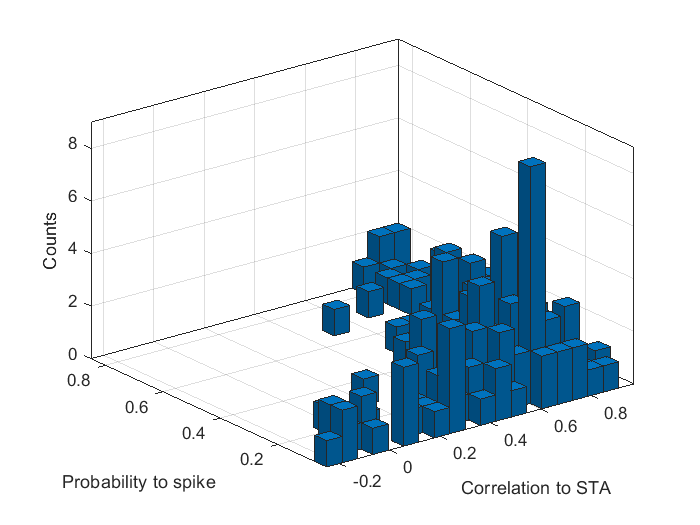


% figure; histogram(similarity_STA_corrcoef);
% title('Similarity histogram with corrcoef measure')
% figure; plot(similarity_STA_corrcoef,Pc_spike_stim, 'o');

figure; histogram2(similarity_STA_corrcoef,Pc_spike_stim',20, 'DisplayStyle','bar3','LineWidth',0.2,'EdgeAlpha',0.3);
xlabel('Correlation to STA');
ylabel('Probability to spike');
zlabel('Counts');

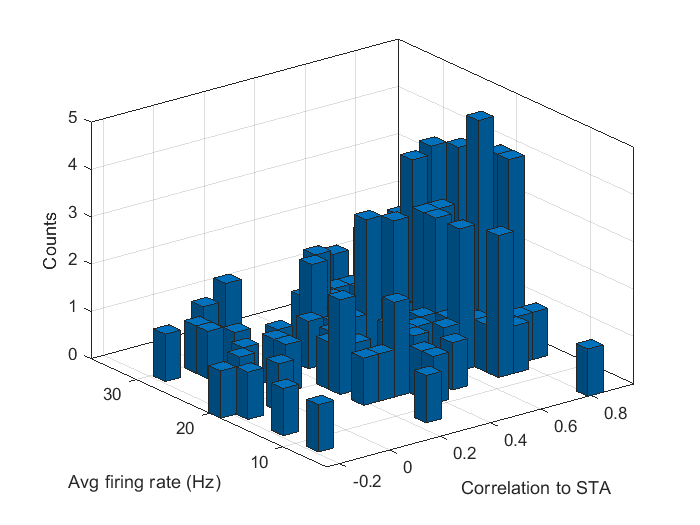


ind = isnan(similarity_STA);
similarity_STA_corrcoef(ind)=[];
similarity_EVec1_corrcoef(ind) = [];
Pc_spike_stim(ind) = [];
FR_spike_stim(ind) = [];
similarity_STA(ind) = [];

figure; histogram2(similarity_STA_corrcoef,FR_spike_stim',20, 'DisplayStyle','bar3','LineWidth',0.2,'EdgeAlpha',0.3);
xlabel('Correlation to STA');
ylabel('Avg firing rate (Hz)');
zlabel('Counts');

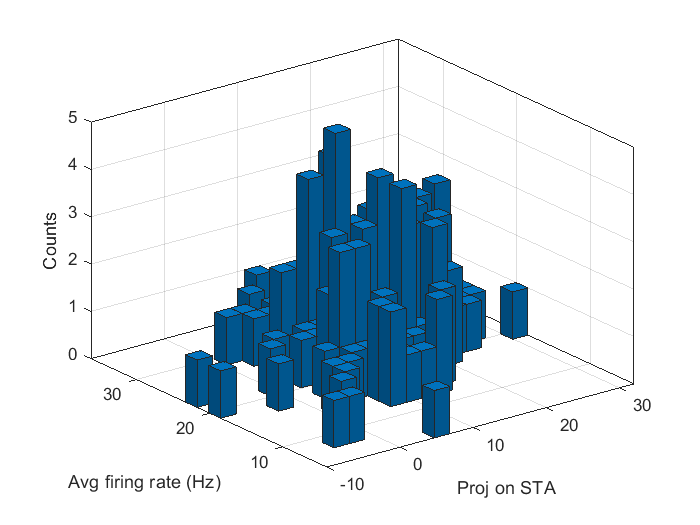


figure; histogram2(similarity_STA,FR_spike_stim',20, 'DisplayStyle','bar3','LineWidth',0.2,'EdgeAlpha',0.3);
xlabel('Proj on STA');
ylabel('Avg firing rate (Hz)');
zlabel('Counts');


% figure;
% % plot(similarity_ev, Pc_spike_stim, '.');
% f = fit([similarity_STA_corrcoef similarity_EVec1_corrcoef], Pc_spike_stim','poly11');
% plot(f,[similarity_STA_corrcoef similarity_EVec1_corrcoef], Pc_spike_stim');


## Non-linear decision function for Pspike and Corrcoef

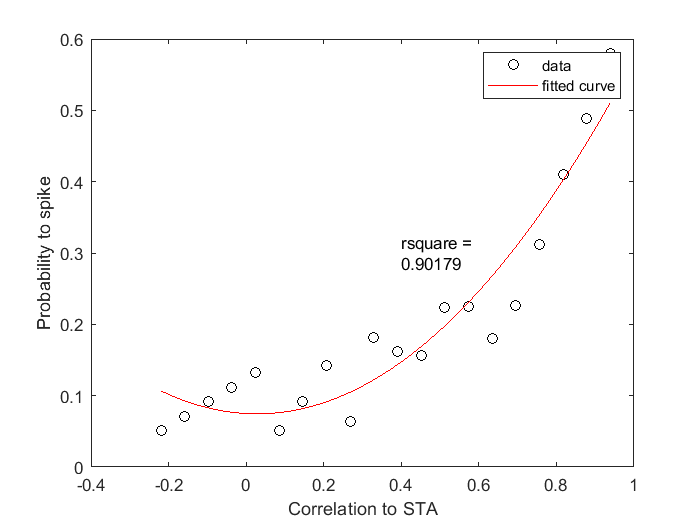

[N,Xedges,Yedges] = histcounts2(similarity_STA_corrcoef,Pc_spike_stim',20);

xBinCenters = Xedges(1:end-1) + diff(Xedges)/2;
yBinCenters = Yedges(1:end-1) + diff(Yedges)/2;

for i =1:20
    pSpikeAvg(i) = sum(N(i,:).*yBinCenters)/sum(N(i,:));
end
ind = isnan(pSpikeAvg);
pSpikeAvg(ind)=[];
xBinCenters(ind) = [];

figure;
[f_pspike, gof] = fit(xBinCenters', pSpikeAvg','poly2');
plot(f_pspike,xBinCenters,pSpikeAvg,'ko');
xlabel('Correlation to STA');
ylabel('Probability to spike');
hold on;
text(0.4,0.3,string(["rsquare =" gof.rsquare]));

gof

gof = struct with fields:
           sse: 0.0402
       rsquare: 0.9018
           dfe: 17
    adjrsquare: 0.8902
          rmse: 0.0486


## Non-linear decision function for Pspike and projection


[N,Xedges,Yedges] = histcounts2(similarity_STA,Pc_spike_stim',20);

xBinCenters = Xedges(1:end-1) + diff(Xedges)/2;
yBinCenters = Yedges(1:end-1) + diff(Yedges)/2;

for i =1:20
    pSpikeAvg(i) = sum(N(i,:).*yBinCenters)/sum(N(i,:));
end
ind = isnan(pSpikeAvg);
pSpikeAvg(ind)=[];
xBinCenters(ind) = [];

figure;
[f_pspike, gof] = fit(xBinCenters', pSpikeAvg','poly2');
plot(f_pspike,xBinCenters,pSpikeAvg,'ko');
xlabel('Projection onto STA');
ylabel('Probability to spike');
hold on;
text(15,10,string(["rsquare =" gof.rsquare]));
gof

## Non-linear decision function for Firing rate and Corrcoef

[N,Xedges,Yedges] = histcounts2(similarity_STA_corrcoef,FR_spike_stim',20);

xBinCenters = Xedges(1:end-1) + diff(Xedges)/2;
yBinCenters = Yedges(1:end-1) + diff(Yedges)/2;

FR_model = [];

for i =1:20
    FR_model(i) = sum(N(i,:).*yBinCenters)/sum(N(i,:));
end
ind = isnan(FR_model);
FR_model(ind)=[];
xBinCenters(ind) = [];

figure;
[f_FR, gof] = fit(xBinCenters', FR_model','poly2');
plot(f_FR,xBinCenters,FR_model,'ko');
xlabel('Correlation to STA');
ylabel('Firing rate');
hold on;
text(0.4,0.3,string(["rsquare =" gof.rsquare]));
gof


## Prediction with corrcoef

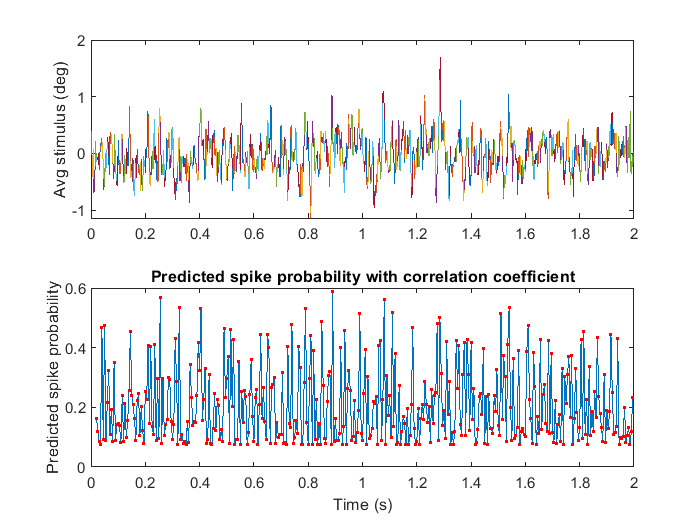

predStepWin = 5e-3*fs; % 1 ms
% predTable = table(spikeloc, FR, Pspike);
time_test_set = time(1:2*fs);

figure;
ax1 = subplot(2,1,1); plot(time_test_set, mean(stimulus_test,1)); hold on;
ylabel('Avg stimulus (deg)');

% ax2 = subplot(3,1,2); plot(time_test_set, )
% ax2 = subplot(2,1,2); plot(time_test_set, mean_gcfr_test_set); hold on;
% xlabel('Time (s)');
% ylabel('Firing rate (Hz)');


pspikePred = [];
timestamps = [];

for iwin = 1:predStepWin:(length(stimulus_test)-stim_window*fs-1)
    test_stim = mean(stimulus_test(:,iwin:iwin+stim_window*fs),1);
    subplot(2,1,1); plot(time_test_set((iwin:iwin+stim_window*fs)), test_stim); hold on;
    corrMat = corrcoef(test_stim,STA);
    corr = corrMat(2);
    timestamps = [timestamps iwin+stim_window*fs+1];
    pspikePred = [pspikePred f_pspike(corr)];
end


ax2 = subplot(2,1,2);plot(time_test_set(timestamps), pspikePred, 'Marker',".","MarkerEdgeColor",'r' );
hold on;
ylabel('Predicted spike probability');
title('Predicted spike probability with correlation coefficient');
xlabel('Time (s)');

## Prediction with projection

predStepWin = 5e-3*fs; % 1 ms
% predTable = table(spikeloc, FR, Pspike);
time_test_set = time(1:2*fs);

figure;
ax1 = subplot(2,1,1); plot(time_test_set, mean(stimulus_test,1)); hold on;
ylabel('Avg stimulus (deg)');

% ax2 = subplot(3,1,2); plot(time_test_set, )
% ax2 = subplot(2,1,2); plot(time_test_set, mean_gcfr_test_set); hold on;
% xlabel('Time (s)');
% ylabel('Firing rate (Hz)');


pspikePred = [];
timestamps = [];

for iwin = 1:predStepWin:(length(stimulus_test)-stim_window*fs-1)
    test_stim = mean(stimulus_test(:,iwin:iwin+stim_window*fs),1);
    subplot(2,1,1); plot(time_test_set((iwin:iwin+stim_window*fs)), test_stim); hold on;
    similarity = dot(test_stim, STA);
    timestamps = [timestamps iwin+stim_window*fs+1];
    pspikePred = [pspikePred f_pspike(similarity)];
end


ax2 = subplot(2,1,2);plot(time_test_set(timestamps), pspikePred, 'Marker',".","MarkerEdgeColor",'r' );
hold on;
ylabel('Predicted spike probability');
title('Predicted spike probability with projection on STA')
xlabel('Time (s)');


## Actual spike probability for test dataset

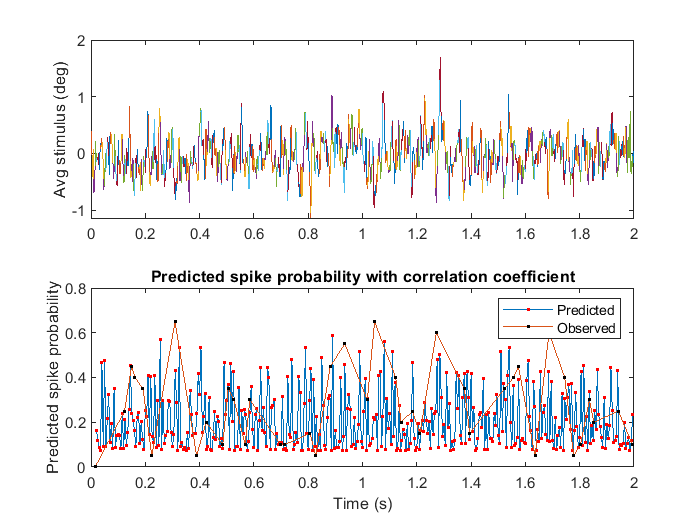

locs_ref = find(raster_data_test(1,:)==1); %spikes of first trial only
ref = locs_ref(1);
Pc_spike_actual = [];

for j = 1:length(locs_ref)
        ref = locs_ref(j);
        
        if ref>stim_window*P.fs && (ref+spike_window)<length(stimulus_model)
            [spike_rows_trials, locs] = find(raster_data_test(:,ref-spike_window : ref+spike_window)==1);
            Pc_spike_actual(j) = length(locs)/nTrials;
 
        end      
end
subplot(2,1,2); plot(locs_ref/fs, Pc_spike_actual, 'Marker',".","MarkerEdgeColor",'k' );
linkaxes([ax1,ax2], 'x');
legend('Predicted','Observed');